clc;clear;

## Prepare fuzzy controller

fis = readfis("assets/triangular_25rules");

## Visualize fuzzy controller

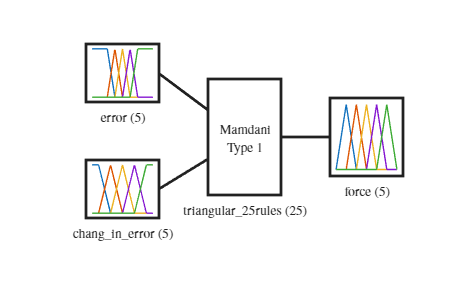

% plot block diagram
plotfis(fis);
fontname('TeX Gyre Termes');
fontsize(10,"points");
exportgraphics(gca,"figures/triangular_25rules_plotfis.svg");

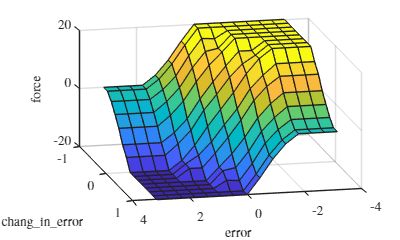

% plot control surface
fig = figure('Position',[0 0 400 240],'Units','points');
gensurf(fis);
view([167.0 25.5]);
fontname(fig,'TeX Gyre Termes');
fontsize(fig,10,"points");
exportgraphics(fig,"figures/triangular_25rules_gensurf.svg");

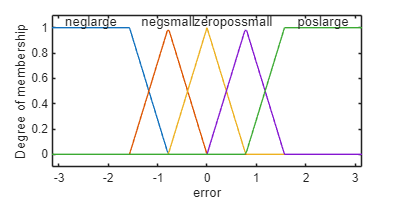

% plot member functions
fig = figure('Position',[0 0 400 200],'Units','points');
fontname(fig,'TeX Gyre Termes');
fontsize(fig,10,"points");
plotmf(fis,"input",1);
exportgraphics(fig,"figures/triangular_25rules_plotmf_error.svg");

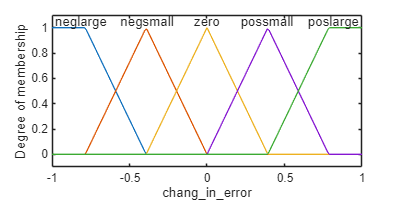

fig = figure('Position',[0 0 400 200],'Units','points');
fontname(fig,'TeX Gyre Termes');
fontsize(fig,10,"points");
plotmf(fis,"input",2);
exportgraphics(fig,"figures/triangular_25rules_plotmf_change_in_error.svg");

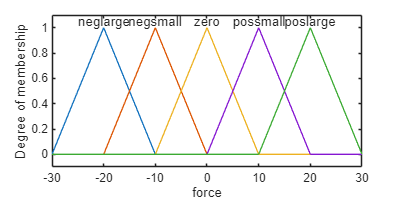

fig = figure('Position',[0 0 400 200],'Units','points');
fontname(fig,'TeX Gyre Termes');
fontsize(fig,10,"points");
plotmf(fis,"output",1);
exportgraphics(fig,"figures/triangular_25rules_plotmf_force.svg");

## Set derivative gain

g0 = 1;
g1 = 0.1;
h = 1;

## Start Simulink

% open_system("pendulum_system");
out=sim("pendulum_system");

## Prepare data for plot

y_data = out.ScopeData.get("y").Values.Data(:,1);
y_time = out.ScopeData.get("y").Values.Time;
u_data = out.ScopeData.get("u").Values.Data(:,1);
u_time = out.ScopeData.get("u").Values.Time;

## Plot data

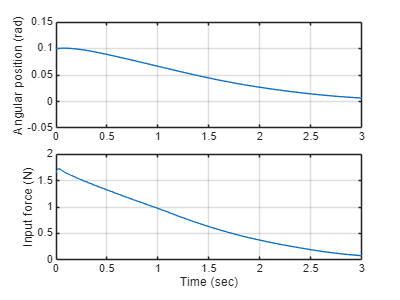

fig = figure('Position',[0 0 400 300],'Units','points');
fontname(fig,'TeX Gyre Termes');
fontsize(fig,10,"points");
tiledlayout("vertical","TileSpacing","compact")

% Angular position
nexttile
plot(y_time,y_data,"DisplayName","y_data");
ylabel("Angular position (rad)");
ylim([-0.05 0.15]);
legend off;
grid on;

% Input force
nexttile
plot(u_time,u_data,"DisplayName","u_data");
xlabel("Time (sec)");
ylabel("Input force (N)");
legend off;
grid on;

exportgraphics(fig,"figures/triangular_25rules_sim_waveform.svg");